# Réponse en fréquence et Compensation

## 1) Récupération des données d'acquisition :

close all;
clear;
clc;

data = readmatrix('test9_data.csv'); % test mesures n°9 retenu
fs = 6250; 

% Extraction
time = data(:, 1);
acceleration = abs(data(:, 2));
sync_data = data(:, 3);

    Le fichier .csv contient les données d'accélération, du temps et la sortie sync du générateur (génère un sweep linéaire d'une durée de 60 sec allant de 1Hz à 121Hz). Le signal sync permet de détecter le début/fin du sweep linéaire qui ne commençait pas au déclenchement de l'acquisition. 

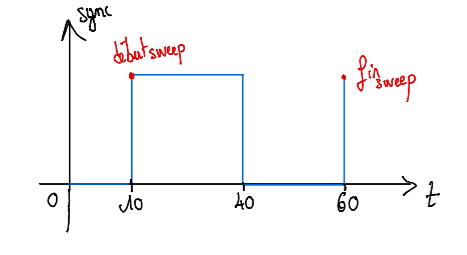

%% Synchronisation des signaux

% Paramètres sweep linéaire
start_freq = 1; 
end_freq = 121;   
duration = 60;   

initial_delay = 9;
initial_delay_index = find(time >= initial_delay, 1, 'first');

% Lisser le signal de synchronisation pour réduire le bruit
smooth_sync = movmean(sync_data(initial_delay_index:end), 100);

% Calcul de la dérivée du signal de synchronisation 
sync_derivative = diff(smooth_sync);
time_derivative = time(initial_delay_index:end-1);


[~, max_indices] = findpeaks(sync_derivative, 'MinPeakHeight', max(sync_derivative) * 0.5);
sweep_start_index = initial_delay_index + max_indices(1) - 1;
sweep_end_index = initial_delay_index + max_indices(end) - 1;

sweep_middle_index = round((sweep_start_index + sweep_end_index) / 2);

sweep_start_time = time(sweep_start_index);
sweep_middle_time = time(sweep_middle_index);
sweep_end_time = time(sweep_end_index);

% Afficher les temps détectés pour vérification
disp(['Sweep start detected at time: ', num2str(sweep_start_time), ' seconds']);

Sweep start detected at time: 9.4438 seconds


disp(['Sweep middle detected at time: ', num2str(sweep_middle_time), ' seconds']);

Sweep middle detected at time: 39.56 seconds


disp(['Sweep end detected at time: ', num2str(sweep_end_time), ' seconds']);

Sweep end detected at time: 69.6762 seconds


Troncage des données pour ne prendre que les données d'accélérations au lancement du sweep linéaire. 

% Ajustement du temps et des données d'accélération pour commencer au début du sweep et finir à la fin du sweep
nb_echantillons = duration * fs;

adjusted_time = time(sweep_start_index:sweep_end_index) - sweep_start_time; 
adjusted_time = adjusted_time(1:nb_echantillons);

adjusted_acceleration = acceleration(sweep_start_index:sweep_end_index);
adjusted_acceleration = adjusted_acceleration(1:nb_echantillons); 


Création d'une fenêtre d'observation pour éviter les effets de bords. 

% Application de la fenêtre de Tukey pour lisser les bords du signal d'accélération
alpha = 0.1; 
tukey_window = tukeywin(length(adjusted_acceleration), alpha);
smoothed_acceleration = adjusted_acceleration .* tukey_window;

Plot de la fft de l'accélération : 

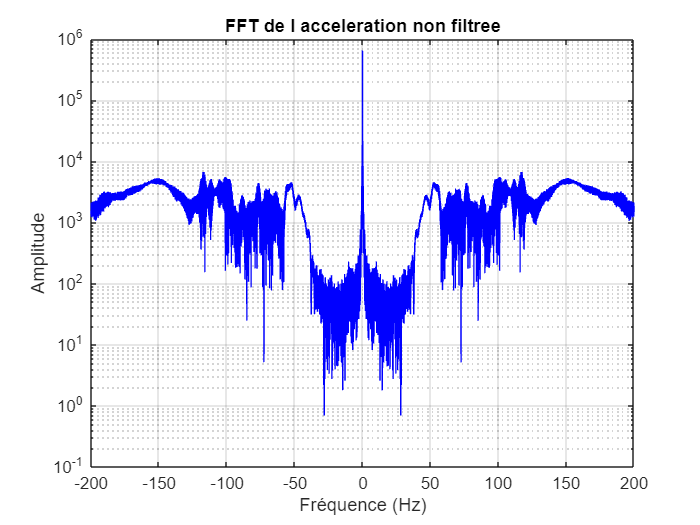

% Calcul de la FFT de l'accélération ajustée
displacement_fft = adjusted_acceleration - mean(adjusted_acceleration);
displacement_fft = fft(adjusted_acceleration);



L = length(displacement_fft);
freq_displacement = (0:L-1)*(fs/L);


displacement_fft_shifted = fftshift(displacement_fft);
freq_displacement_shifted = (-L/2:L/2-1)*(fs/L);

figure;
plot(freq_displacement_shifted, abs(displacement_fft_shifted), 'b');
xlabel('Fréquence (Hz)');
ylabel('Amplitude');
yscale log;
xlim([-200 200]);
title('FFT de l acceleration non filtree');
grid on;

Création d'un filtre passe-bande pour m'intéresser seulement aux fréquences entre 1Hz et 121Hz.

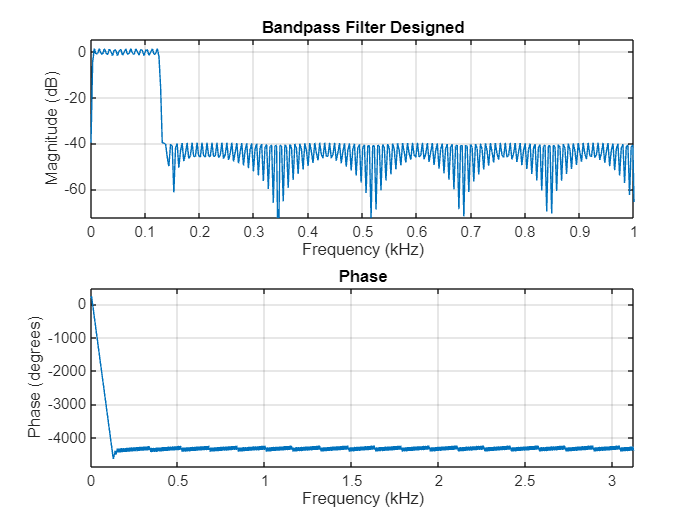

% Creation du filtre

rp = 3;
rs = 40;
f = [0 5 125 130];
a = [0 1 0]; 

dev = [10^(-rs/20) (10^(rp/20)-1)/(10^(rp/20)+1) 10^(-rs/20)]; 
[n,fo,ao,w] = firpmord(f,a,dev,fs);
b_bandpass = firpm(n,fo,ao,w);

freqz(b_bandpass,1,1024,fs); xlim([0;1]);
title('Bandpass Filter Designed')

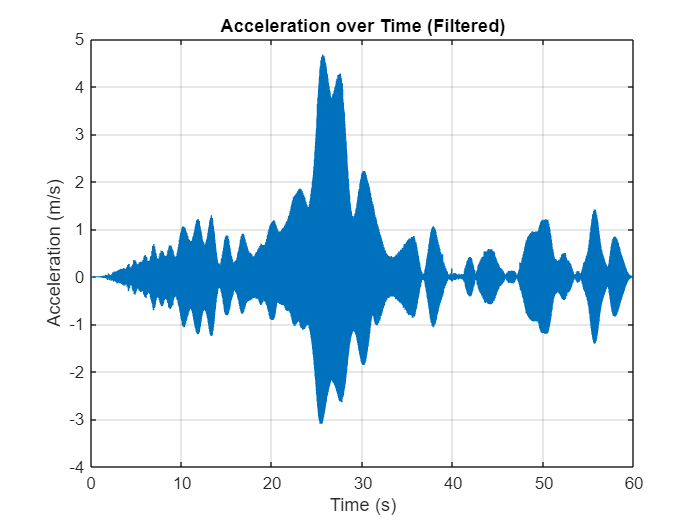

% Application du filtre passe-bande
acceleration_filtered_bandpass = filtfilt(b_bandpass, 1, smoothed_acceleration);

% Corrige la dérive du capteur
acceleration_filtered_bandpass = detrend(acceleration_filtered_bandpass,2);

% Plot de l'accélération filtrée en fonction du temps
figure (1);
plot(adjusted_time, acceleration_filtered_bandpass);
title('Acceleration over Time (Filtered)');
xlabel('Time (s)');
ylabel('Acceleration (m/s)');
grid on;

FFT de l'accélération filtrée : 

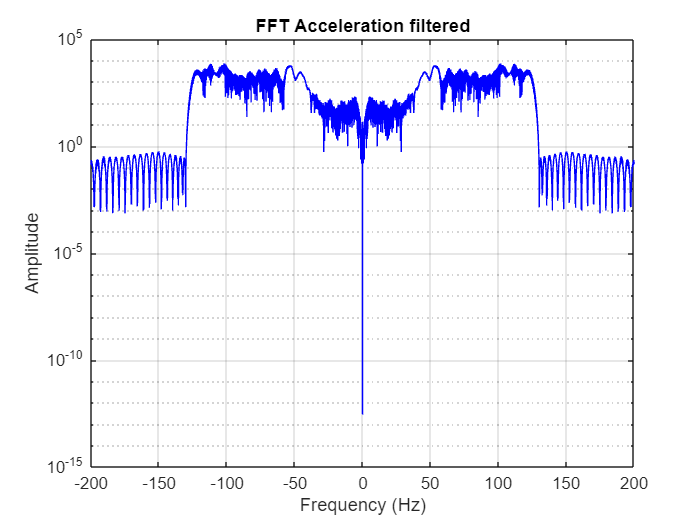

% Calcul de la FFT de l'accélération ajustée
displacement_fft = fft(acceleration_filtered_bandpass);

% Calcul des fréquences associées
L = length(displacement_fft);
freq_displacement = (0:L-1)*(fs/L);

% Décalage de la FFT pour placer la fréquence zéro au centre
displacement_fft_shifted = fftshift(displacement_fft);

% Ajustement des fréquences pour la FFT décalée
freq_displacement_shifted = (-L/2:L/2-1)*(fs/L);

% Tracé des résultats de la FFT
figure(2);
plot(freq_displacement_shifted, abs(displacement_fft_shifted), 'b');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
xlim([-200 200]);
yscale log;
title('FFT Acceleration filtered');
grid on;

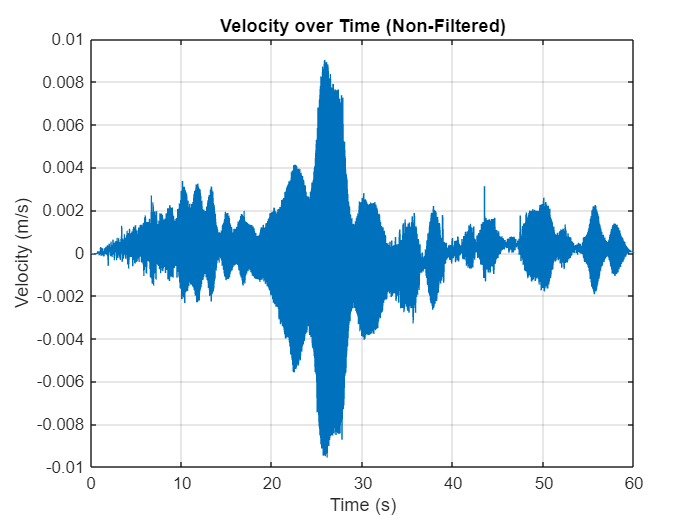

% Intégration pour obtenir la vitesse

velocity = cumtrapz(adjusted_time, acceleration_filtered_bandpass);

figure(3);
plot(adjusted_time, velocity);
title('Velocity over Time (Non-Filtered)');
xlabel('Time (s)');
ylabel('Velocity (m/s)');
grid on;

Calcul de la FFT de la vitesse non filtrée : 

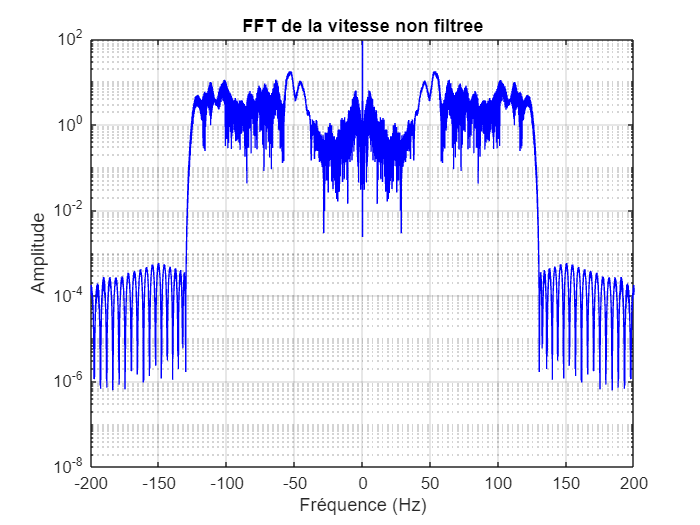

% Calcul de la FFT de la vitesse ajustée
velocity_fft = fft(velocity);


L = length(velocity);
freq_velocity = (0:L-1)*(fs/L);


velocity_fft_shifted = fftshift(velocity_fft);
freq_velocity_shifted = (-L/2:L/2-1)*(fs/L);

% Tracé des résultats de la FFT
figure(4);
plot(freq_velocity_shifted, abs(velocity_fft_shifted), 'b');
xlabel('Fréquence (Hz)');
ylabel('Amplitude');
xlim([-200 200]);
yscale log;
title('FFT de la vitesse non filtree');
grid on;

Signal de la vitesse filtrée : 

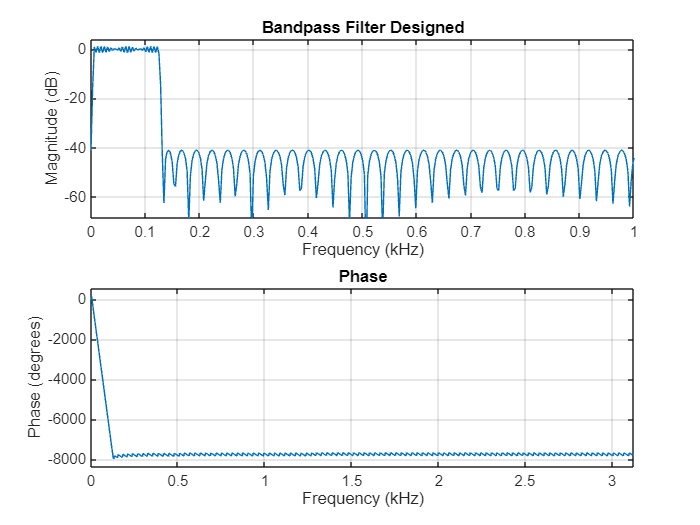

% Creation du filtre

rp = 3;
rs = 40;
f = [2 5 125 130];
a = [0 1 0]; 

dev = [10^(-rs/20) (10^(rp/20)-1)/(10^(rp/20)+1) 10^(-rs/20)]; 
[n,fo,ao,w] = firpmord(f,a,dev,fs);
b_bandpass = firpm(n,fo,ao,w);

freqz(b_bandpass,1,1024,fs); xlim([0;1]);
title('Bandpass Filter Designed')

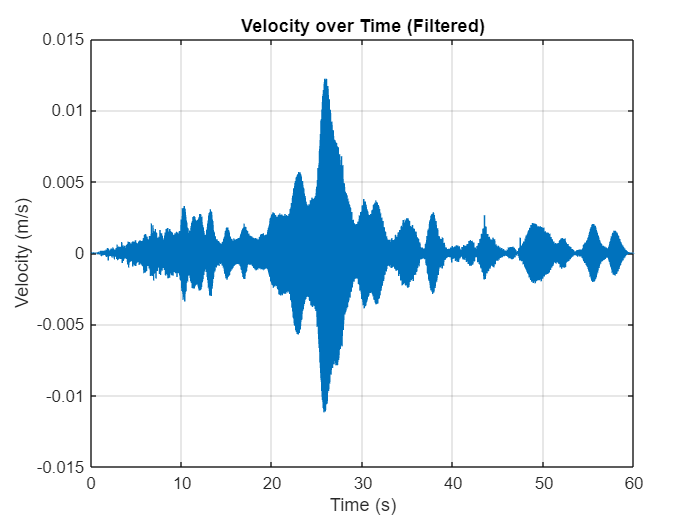

velocity_filtered_bandpass = filtfilt(b_bandpass, 1, velocity);

% Plot de la vitesse filtrée 

figure(4);
plot(adjusted_time, velocity_filtered_bandpass);
title('Velocity over Time (Filtered)');
xlabel('Time (s)');
ylabel('Velocity (m/s)');
grid on;

FFT de la vitesse filtrée

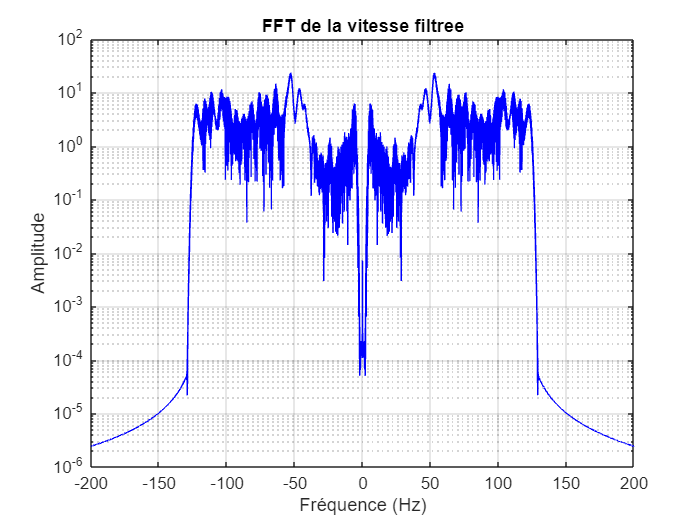

% Calcul de la FFT de la vitesse ajustée
vitesse_fft = fft(velocity_filtered_bandpass);


L = length(vitesse_fft);
freq_displacement = (0:L-1)*(fs/L);


vitesse_fft_shifted = fftshift(vitesse_fft);
freq_vitesse_shifted = (-L/2:L/2-1)*(fs/L);

% Tracé des résultats de la FFT
figure(2);
plot(freq_vitesse_shifted, abs(vitesse_fft_shifted), 'b');
xlabel('Fréquence (Hz)');
ylabel('Amplitude');
xlim([-200 200]);
yscale log;
title('FFT de la vitesse filtree');
grid on;

Pareil pour le déplacement : 

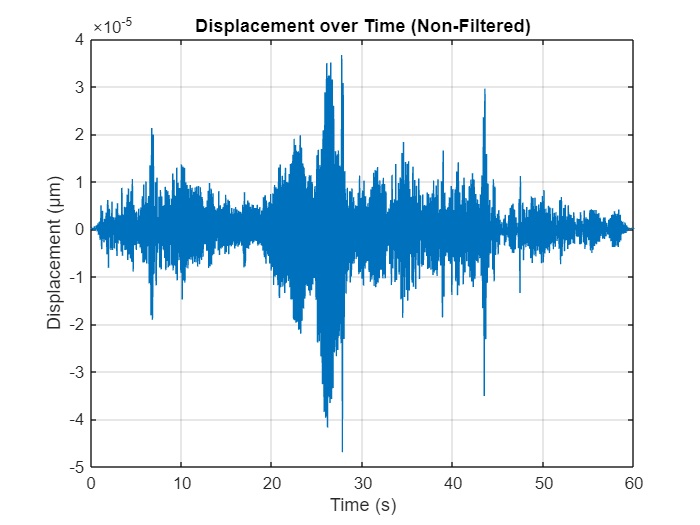

% Intégration pour obtenir le déplacement
displacement = cumtrapz(adjusted_time, velocity_filtered_bandpass);

figure(3);
plot(adjusted_time, displacement);
title('Displacement over Time (Non-Filtered)');
xlabel('Time (s)');
ylabel('Displacement (µm)');
grid on;

Calcul de la FFT : 

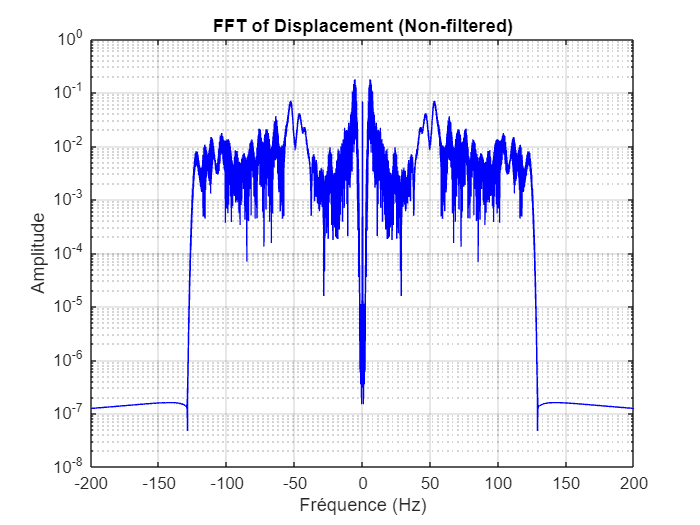

% Calcul de la FFT du déplacement non filtré 
displacement_fft = fft(displacement);

% Calcul des fréquences associées
L = length(displacement_fft);
freq_displacement = (0:L-1)*(fs/L);

displacement_fft_shifted = fftshift(displacement_fft);
freq_displacement_shifted = (-L/2:L/2-1)*(fs/L);

figure;
plot(freq_displacement_shifted, abs(displacement_fft_shifted), 'b');
xlabel('Fréquence (Hz)');
ylabel('Amplitude');
yscale log;
xlim([-200 200]);
title('FFT of Displacement (Non-filtered)');
grid on;

Création du filtre déplacement : 

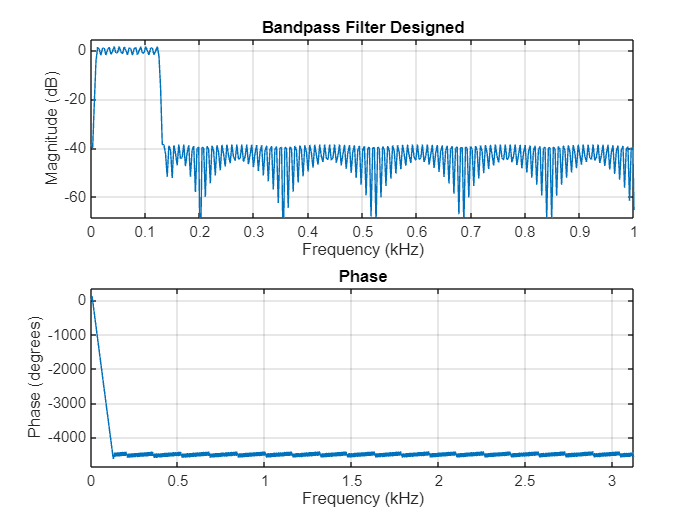

% Creation du filtre

rp = 3;
rs = 40;
f = [5 10 125 130];
a = [0 1 0]; 

dev = [10^(-rs/20) (10^(rp/20)-1)/(10^(rp/20)+1) 10^(-rs/20)]; 
[n,fo,ao,w] = firpmord(f,a,dev,fs);
b_bandpass = firpm(n,fo,ao,w);

freqz(b_bandpass,1,1024,fs); xlim([0;1]);
title('Bandpass Filter Designed')

Application du filtre au déplacement : 

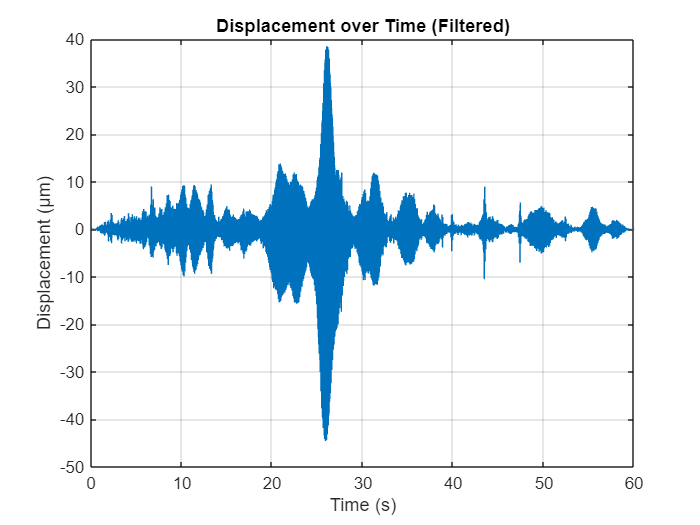

displacement_filtered_bandpass = filtfilt(b_bandpass, 1, displacement)* 10^6;

% Plot du déplacement filtré 

figure(4);
plot(adjusted_time, displacement_filtered_bandpass);
title('Displacement over Time (Filtered)');
xlabel('Time (s)');
ylabel('Displacement (µm)');
grid on;

FFT du déplacement filtré : 

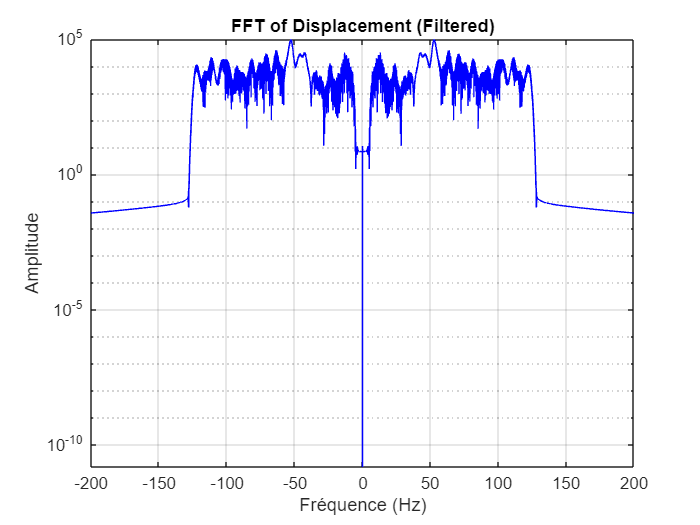

% Soustraction de la moyenne pour éliminer la composante DC
displacement_filtered_bandpass = displacement_filtered_bandpass - mean(displacement_filtered_bandpass);

% Calcul de la FFT du déplacement non filtré 
displacement_fft = fft(displacement_filtered_bandpass);

L = length(displacement_fft);
freq_displacement = (0:L-1)*(fs/L);

displacement_fft_shifted = fftshift(displacement_fft);
freq_displacement_shifted = (-L/2:L/2-1)*(fs/L);

figure(1);
plot(freq_displacement_shifted, abs(displacement_fft_shifted), 'b');
xlabel('Fréquence (Hz)');
ylabel('Amplitude');
yscale log;
xlim([-200 200]);
title('FFT of Displacement (Filtered)');
grid on;

Réponse en fréquence du modèle : 

% Paramètres du balayage linéaire
start_freq = 1; 
end_freq = 121;   
duration = 60; 
fs = 6250; % Fréquence d'échantillonnage
N = length(displacement_filtered_bandpass); 

% Calcul des paramètres de segmentation
num_freqs = end_freq - start_freq + 1;
samples_per_freq = round((fs * duration) / num_freqs); 


% Initialisation des vecteurs de réponse en fréquence
frequencies = linspace(start_freq, end_freq, num_freqs);
P1_disp_filtered = zeros(1, num_freqs);
phase_disp_filtered = zeros(1, num_freqs);

for n = 1:num_freqs
    
    % Indices du segment actuel
    start_idx = (n-1) * samples_per_freq + 1;
    end_idx = min(n * samples_per_freq, length(displacement_filtered_bandpass));
    
    % Extraire le segment de déplacement
    segment_disp = displacement_filtered_bandpass(start_idx:end_idx);
    
    % Générer le signal sinusoïdal correspondant à la fréquence actuelle
    current_freq = frequencies(n);
    t_segment = adjusted_time(start_idx:end_idx); 
    
    % Sweep linéaire 
    reference_signal = 5.66 * sin(2 * pi * current_freq * t_segment);
    
    % Appliquer la FFT sur le segment de déplacement et le signal de référence
    L_segment = length(segment_disp);
    Y_disp_segment = fft(segment_disp);
    Y_ref_segment = fft(reference_signal);
    
    % Extraire la magnitude et la phase de la composante fondamentale
    [~, max_idx] = max(abs(Y_ref_segment));
    P1_disp_filtered(n) = abs(Y_disp_segment(max_idx)) / (L_segment/2); 
    phase_disp_filtered(n) = angle(Y_disp_segment(max_idx)) - angle(Y_ref_segment(max_idx)); 
    
    % Normalisation de la phase pour qu'elle soit entre -pi et pi
    phase_disp_filtered(n) = mod(phase_disp_filtered(n) + pi, 2*pi) - pi;
end

% Conversion des fréquences en rad/s
frequencies_rad = frequencies * 2 * pi;

% Création du modèle avec magnitude et phase
response = P1_disp_filtered .* exp(1i * phase_disp_filtered);  
sys = frd(response, frequencies_rad);

Réponse en fréquence du système : 

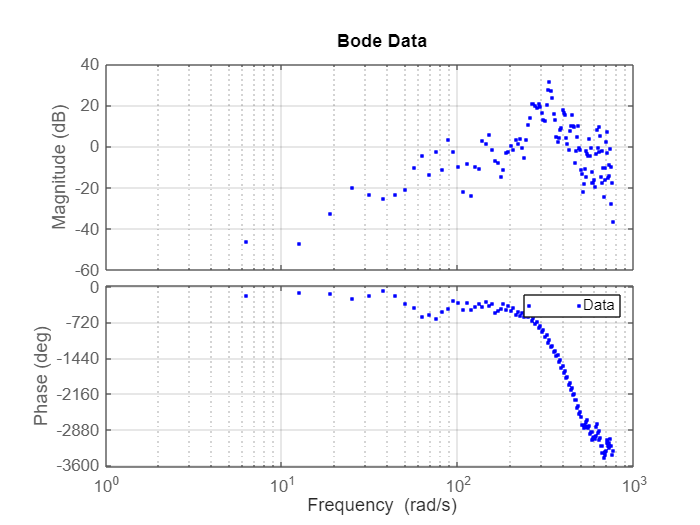

% Reponse en fréquence données 
figure;
bode(sys, '.');
grid on;
title('Bode Data');
legend('Data');